***3 - c***

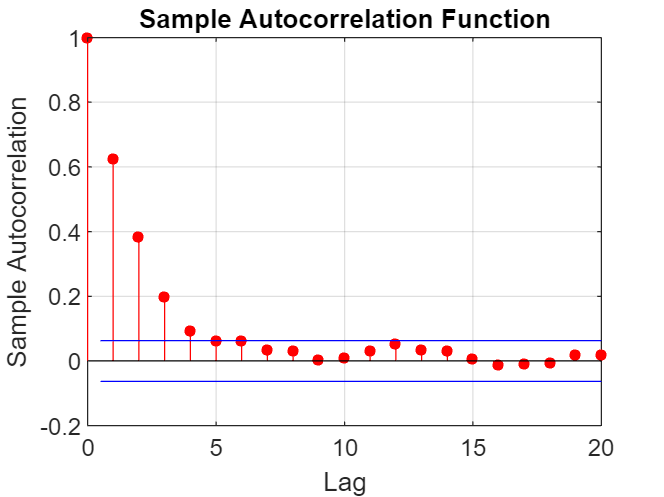

clc;
clear variables;
rng('default');
d1 = 0.6; %AR coefficient at lag = 1
N = 1000; %No of observations
AR1 = arima('Constant',0,'AR',{0.6},'ARlags',[1],'Variance',1); %Creating AR(1) Process
Y_ar1 = simulate(AR1,N); %Simulating AR(1) process for 1000 Observations
autocorr(Y_ar1) %Plotting Autocorrelation Function(ACF) estimate values for lags 

p = autocorr(Y_ar1(:,1)); %Autocorrelation estimate value(ACF) for all lag 
p_t = zeros(21,1); %true values of ACF for all lags
for i = 0:20
    p_t(i+1) = power(0.6,i); %ACF for lag = i
end
p(2) %ACF for lag=1 - Analytical

ans = 0.6268

p_t(2) %ACF for lag=2 - Theoritical

ans = 0.6000

p(3) %ACF for lag=2 - Analytical

ans = 0.3843

p_t(3) %ACF for lag=2 - Theoritical

ans = 0.3600

p - p_t %Difference between Analytical and Theoritical ACF values 

ans =          0
    0.0268
    0.0243
   -0.0164
   -0.0340
   -0.0149
    0.0177
    0.0088
    0.0159
   -0.0065


phi2 = (p(3) - (p(2)*p(2))) / (1-(p(2)*p(2))) %PACF for lag=2 - Analytical

phi2 = -0.0142

phi2_t = (p_t(3) - (p_t(2)*p_t(2))) / (1-(p_t(2)*p_t(2))) %PACF for lag=2 - Theoritical

phi2_t = 0

phi2 - phi2_t %Difference between Analytical and Theoritical ACF values 

ans = -0.0142